format longg
CP = py.importlib.import_module("CoolProp.CoolProp");

zeta_ind = 0.2;
zeta_boj_90 = 0.30;
zeta_boj_135 = zeta_boj_90 * 1.5;
zeta_boj_180 = zeta_boj_90 * 2;
zeta_buffer = 1 + 0.25;
zeta_flow = 1;
zeta_filter = 3;
zeta_skue = zeta_buffer;


zeta_total = zeta_ind + 5*zeta_boj_90 + 3*zeta_boj_135 + zeta_boj_180...
    + zeta_buffer + zeta_flow + zeta_filter + zeta_skue

zeta_total =                      10.15


**For væske**

L = 1.95; %m
t = 0.00080; %m
d = 0.00794 - 2*t %m

d =                    0.00634


d_i = 0.00952 - 2*t %m diameteren ud af kondensatoren

d_i =                    0.00792



c_i = 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren

% c * d^2 = d_i^2 * c_i %countinuitetsligningen
c = d_i^2 * c_i / d^2

c =         0.0930250384859867



rho = 1186.61436781861; %kg/m^3 




nu = CP.PropsSI('V', 'H', 242310, 'P', 886810, 'R134a') % |not_imposed %m^2/s  

nu =       0.000182597977122283


Re = c * d / nu 

Re =           3.22993032724667



% Re < 2300 dermed laminart flow


% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

lambda =           19.8146688986188



Delta_p_ror = lambda * L * c^2 * rho / (d * 2)

Delta_p_ror =           31290.4275129754



Delta_p = zeta_total * (rho * c^2)/ 2

Delta_p =           52.1129149108947


**For gas**

c = 2.26638867101572; %m/s    
rho = 31.2106794247976; %kg/m^3 



L = 7 %1.95%1.95 %m

L =      7


t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                    0.00792



nu = CP.PropsSI('V', 'H', 390410, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

nu =       1.01936374199676e-05


Re = c * d / nu 

Re =           1760.88255202052



% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879



lambda = 64/Re  % <-----------

lambda =         0.0363454109568882



Delta_p_ror = lambda * L * c^2 * rho / (d * 2)

Delta_p_ror =           2574.92421052739



% Delta_p = zeta_total * (rho * c^2)/ 2


For Fordamperen

c = 2.26638867101572; %m/s     
rho = CP.PropsSI('D', 'H', 242310, 'P', 132700, 'R134a')%1186.61436781861; %kg/m^3 

rho =           20.8092484627125





L = 7 %1.95%1.95 %m

L =      7


t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                    0.00792



nu = CP.PropsSI('V', 'H', 242310, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

nu =       9.79656098606867e-06


Re = c * d / nu 

Re =           1832.25504337392



% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879



lambda = 64/Re  % <-----------

lambda =         0.0349296350589655



Delta_p_ror = lambda * L * c^2 * rho / (d * 2)

Delta_p_ror =           1649.91696415077



% Delta_p = zeta_total * (rho * c^2)/ 2

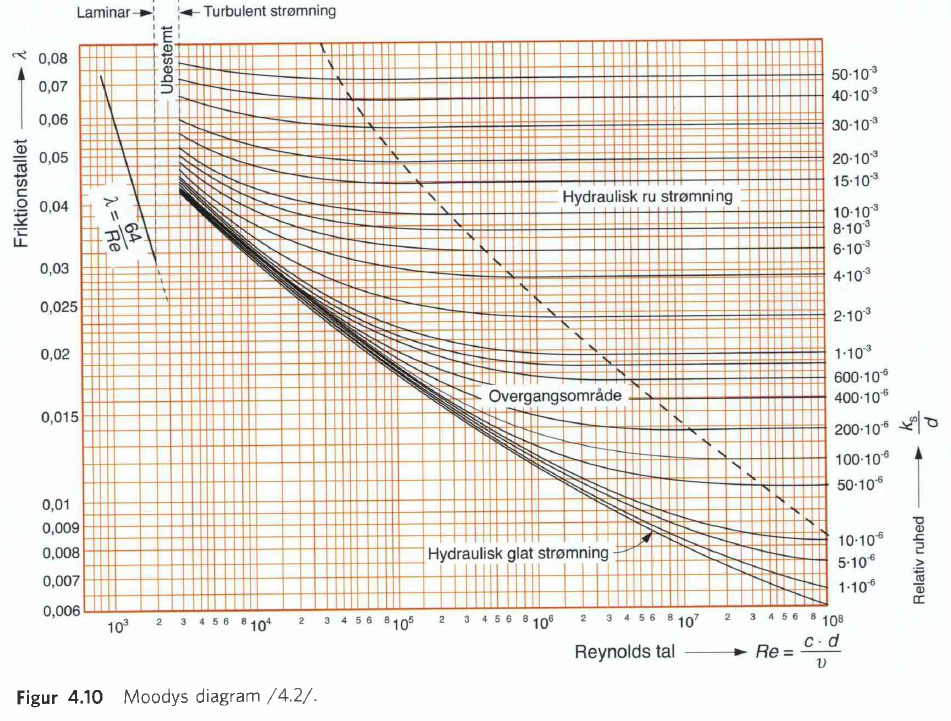

Video til coolprop

[https://www.youtube.com/watch?v=XvR10Fjph7U](https://www.youtube.com/watch?v=XvR10Fjph7U) 

For coolprop

[https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png](https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png)